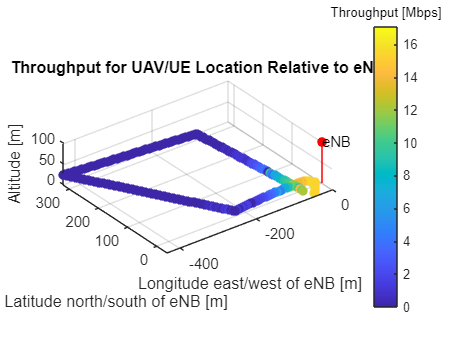

clear

% Log imported as a table. This log file will be the merged log file.
% Access a column/variable, can use table(:,i).
% Access a row, can use table(i,:).
vehicleOutnew = readtable('vehicleOutnew.csv', 'VariableNamingRule','preserve');
%vehicleOutnew(:,1)

eNB_lati = 35.727479;       % Base station latitude for relative coordinates.
eNB_long = -78.695791;      % Base station longitude for relative coordinates.
gps_to_meters = 111139;     % Conversion from GPS coordinates to meters.

long = vehicleOutnew.Longitude;     % Longitude [GPS]
lati = vehicleOutnew.Latitude;      % Latitude [GPS]
alti = vehicleOutnew.Altitude;      % Altitude [m]
%thru = vehicleOutnew.thoughput;     % Throughput from iperf in Mbps
thru = vehicleOutnew.('thoughput');     % Throughput from iperf in Mbps

long_m = (long - eNB_long)*gps_to_meters;
lati_m = (lati - eNB_lati)*gps_to_meters;

% Create 3D scatter plot, colorcode the values based on throughput values.
scatter3(long_m,lati_m,alti, 40, thru, 'filled')
hold on
stem3(0,0,100,'filled', 'r')
text(0,0,100,'eNB')
title('Throughput for UAV/UE Location Relative to eNB')
xlabel('Longitude east/west of eNB [m]')
ylabel('Latitude north/south of eNB [m]')
zlabel('Altitude [m]')

axis equal

% Add colorbar.
cb = colorbar();
%set(cb,'position',[0.9 .5 .02 .35])
title(cb, 'Throughput [Mbps]')
hold off